# Seed Dynamics ODE Test

Integration harness for seed6DOFODE. Builds the same rectangular test seed used in Spinning_Seed_Dynamics_Test.mlx, adds the fluid/gravity parameters required by the dynamics RHS (never set anywhere else), runs a full ode45 integration, then plots the resulting 3D trajectory and Euler-angle rates.

Sections: 1. Setup seed shape, mass, and environment parameters 2. Visualize seed shape (sanity check before integrating) 3. Run the dynamics (ode45) 4. Visualize the 3D trajectory and Euler-angle rates

NOTE: seed6DOFODE has never been run. Per the handoff doc, smoke-test it with a single direct call (xdot = seed6DOFODE(0, x0, seedParams); check finite, a(2) ~ -9.81 when aero is small, dq finite) BEFORE trusting the full ode45 run in Section 3.

addpath(genpath("physics"));
addpath("visualization");

## 1. Setup seed shape, mass, and environment parameters

Geometry & material parameters (matches Spinning_Seed_Dynamics_Test.mlx)

spanLength    = 0.050;   % spanwise length,  body z (m)
chordLength   = 0.015;   % chord length,     body x (m)
thickness     = 0.002;   % plate thickness           (m)
bulkDensity   = 65;    % bulk material density     (kg/m^3)
arealDensity  = bulkDensity * thickness;   % areal density (kg/m^2)
totalDiasporeMass = spanLength*chordLength*thickness*bulkDensity

totalDiasporeMass = 9.7500e-05


% Strip discretisation
numStrips = 10;   % number of spanwise aerodynamic strips

% Time vector for the mass/inertia time series. Mass is constant for this
% symmetric seed (fixed nut), so a single sample is sufficient.
tSamples = 0;   % (s)

% Seed wing polyshape (drawing frame: x = spanwise, y = chordwise).
% Rectangle centred at the origin in both axes.
x_half = spanLength  / 2;   % half-span  in drawing x = body z (m)
y_half = chordLength / 2;   % half-chord in drawing y = body x (m)

wingPolyshape = polyshape( ...
    [-x_half,  x_half,  x_half, -x_half], ...   % drawing-x corners (spanwise)
    [-y_half, -y_half,  y_half,  y_half] );      % drawing-y corners (chordwise)

% Nut mass & position. Nut placed at the geometric centre -> body origin.
nutMass = 75e-6;         % kg
nutPos  = [0; 0.005; 0];    % body frame [x;y;z] (m)

% Assemble seedParamsIn
bsp.seedShape     = wingPolyshape;
bsp.seedDensity   = arealDensity;                        % (kg/m^2)
bsp.seedThickness = thickness;                           % (m)
bsp.numStrips     = numStrips;
bsp.tSamples      = tSamples;                             % (s)
bsp.nutMass_t     = nutMass * ones(size(tSamples));       % Nx1
bsp.nutPos_t      = repmat(nutPos, 1, numel(tSamples));   % 3xN

seedParamsIn.baseSeedParams = bsp;

% Build the full seed parameter struct: strip geometry, CoM(t), I_G(t), I_G_dot(t).
seedParams = setupSeedShapeAndMass(seedParamsIn);

% Environment parameters required by seed6DOFODE but not set by
% setupSeedShapeAndMass (see HANDOFF §4 "Required seedParams fields").
seedParams.rhoFluid = 1.225;   % fluid (air) density (kg/m^3)
seedParams.g        = 9.81;    % gravity magnitude (m/s^2)
% seedParams.aero is left unset -- computeAeroCoeffs falls back to its
% default (exact minimal_imp) empirical coefficients.

## 2. Visualize seed shape

Sanity check: confirm the geometry looks right before integrating.

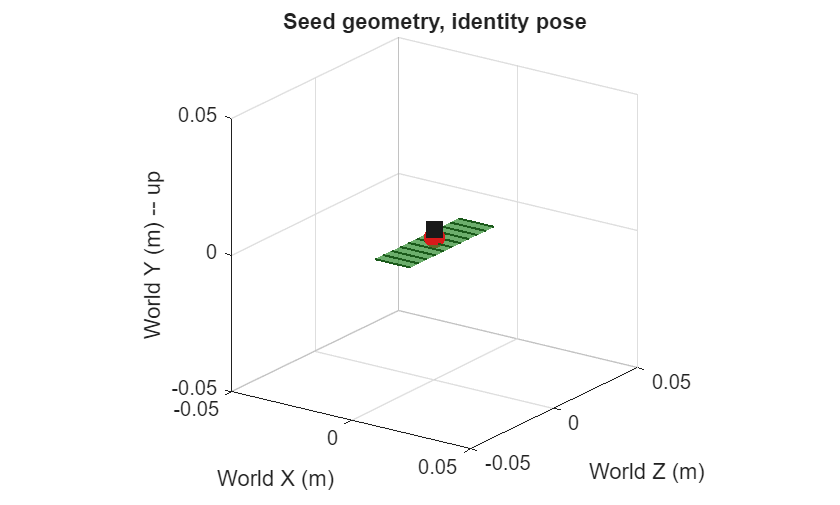

figure('Name', 'Seed shape sanity check');
visualizeSeedShape(seedParams, eye(3), [0;0;0], struct());
axis equal; grid on;
xlim([-0.05 0.05]); ylim([-0.05 0.05]); zlim([-0.05 0.05]);
xlabel('World X (m)'); ylabel('World Z (m)'); zlabel('World Y (m) -- up');
title('Seed geometry, identity pose');
view(35, 20);

## 3. Run the dynamics

r0     = [0; 0; 0];
%q0     = [1; 0; 0; 0];
q0 = eul2quat([0 0 pi/4],'XYZ')';
v0     = [0; 0; 0];
omega0 = [0;  0;  0];

x0 = [r0; q0; v0; omega0];

tspan = 0:0.003:5;   % integration horizon (s)

odeOpts = odeset('RelTol', 1e-6, 'AbsTol', 1e-8);
[tOut, xOut] = ode45(@(t, x) seed6DOFODE(t, x, seedParams), tspan, x0, odeOpts);

% xOut columns: [ r(1:3), q(4:7), v(8:10), omega(11:13) ]. ode45 discards the
% optional `intermediates` output of seed6DOFODE -- if per-strip quantities
% (alpha, CT, CD, ...) are needed later, re-call seed6DOFODE on each row of
% xOut in post-processing (see HANDOFF §6 "known gotchas").

## 4. Visualize the 3D trajectory and Euler-angle rates

--- 3D CoM trajectory ---

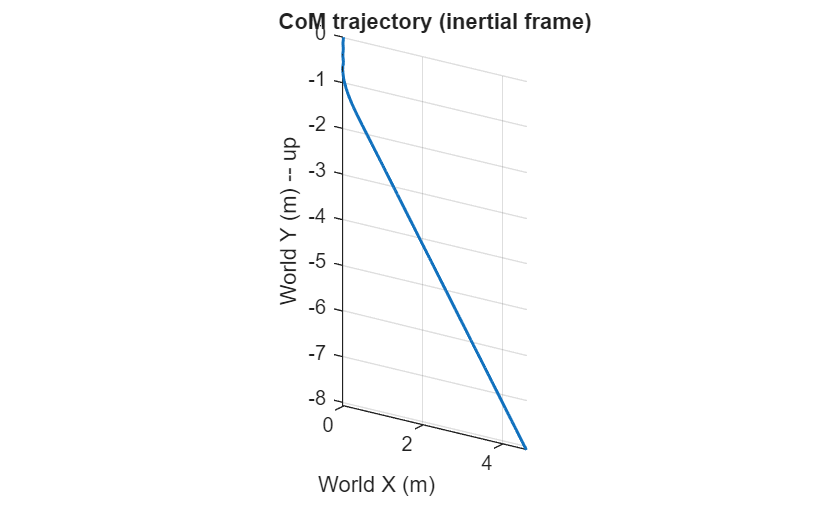

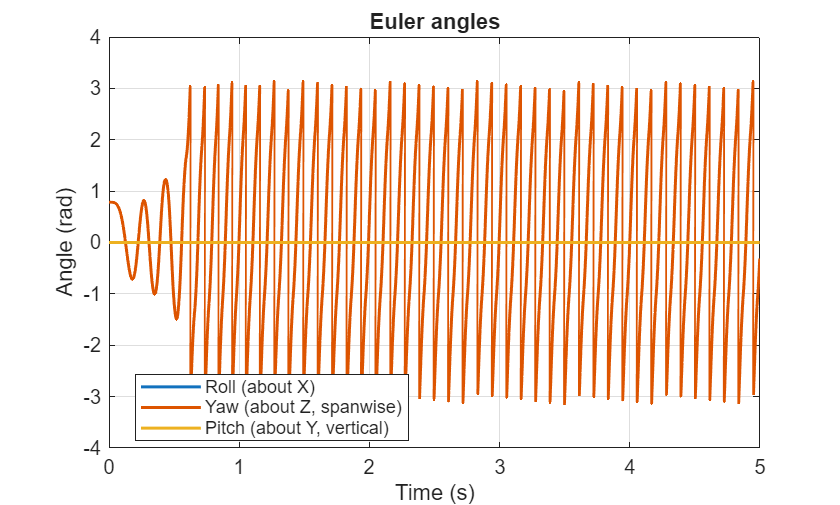

visualizeSeedTrajectory(tOut, xOut(:,1:3).', xOut(:,4:7).');

## 5. Visualize the output

traj.t             = tOut;
traj.quat          = xOut(:, 4:7).';
traj.comPos_world  = xOut(:, 1:3).';
traj.comVel_world  = xOut(:,8:10).';
traj.comOmega_body = xOut(:,11:13).';
% comPos_body omitted -> animateSeed falls back to massParams.com_t ([0;0;0]).

opts = struct();
opts.outputFolder = 'C:\Users\yohan\OneDrive\Documents\Research Stuff\Seed Dynamics Code\Outputs\anim_offset_drop';
opts.videoFile    = 'C:\Users\yohan\OneDrive\Documents\Research Stuff\Seed Dynamics Code\Outputs\anim_offset_drop\anim_offset_drop.mp4';
opts.fps          = 10;
opts.axisMode     = 'follow';
opts.zoomFactor   = 1;
opts.frameStep    = 5;
opts.showVels     = false;
opts.velOpts.showTotal     = false;    % total strip velocities
opts.velOpts.showProjected = false;
opts.velOpts.scale         = 0.04;

animateSeed(seedParams, traj, opts);

animateSeed: 9% done (31/334 frames)
animateSeed: 19% done (64/334 frames)
animateSeed: 29% done (97/334 frames)
animateSeed: 39% done (131/334 frames)
animateSeed: 49% done (164/334 frames)
animateSeed: 59% done (198/334 frames)
animateSeed: 69% done (231/334 frames)
animateSeed: 79% done (264/334 frames)
animateSeed: 89% done (298/334 frames)
animateSeed: 99% done (331/334 frames)
animateSeed: wrote 334 frames to video "C:\Users\yohan\OneDrive\Documents\Research Stuff\Seed Dynamics Code\Outputs\anim_basic_drop\anim_basic_drop.mp4".
